# TP #09 - Ejercicio 05

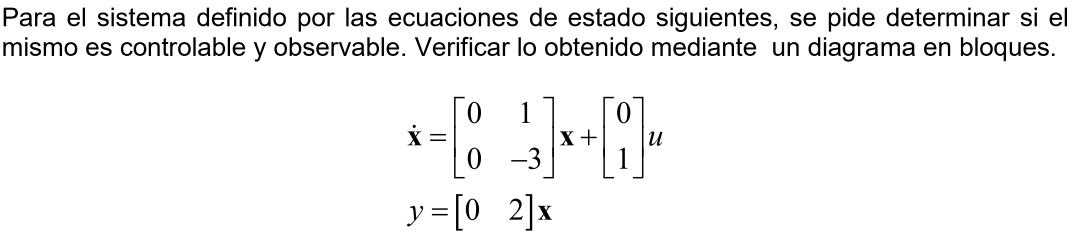

Primero obtenemos las matrices de controlabilidad y observabilidad


$$\begin{array}{l}
\left\lbrack C_o \right\rbrack =\left\lbrack \begin{array}{cc}
B & \mathrm{AB}
\end{array}\right\rbrack \\
\left\lbrack C_o \right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
1 & -3
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
\left\lbrack O_{\mathrm{bs}} \right\rbrack =\left\lbrack \begin{array}{c}
C\\
\mathrm{CA}
\end{array}\right\rbrack \\
\left\lbrack O_{\mathrm{bs}} \right\rbrack =\left\lbrack \begin{array}{cc}
0 & 2\\
0 & -6
\end{array}\right\rbrack 
\end{array}$$


Calculamos en MATLab los rangos para determinar controlabilidad y observabilidad,

A = [0, 1; 0, -3];
B = [0; 1];
C = [0, 2];
Co=[B A*B];
Obs = [C; C*A];
Size_Co = size(Co);
R_Co = rank(Co);
Size_Obs = size(Obs);
R_Obs = rank(Obs);
if R_Co >= (Size_Co(2))
    disp('El sistema es Controlable');
else
    disp('El sistema no es Controlable');
end

El sistema es Controlable



if R_Obs >= (Size_Obs(2))
    disp('El sistema es Observable');
else
    disp('El sistema no es Observable');
end

El sistema no es Observable


Diagrama en bloques,